%% Take picture from Table
format shortG
red = 1.1;
green = 1.2;
blue = 1.3;
yellow = 1.4;

CameraCalibration;


			Standard Errors of Estimated Camera Parameters
			----------------------------------------------

Intrinsics
----------
Focal length (pixels):   [ 1333.7707 +/- 2.9103     1332.8945 +/- 2.8864  ]
Principal point (pixels):[  767.0637 +/- 1.2716      591.1662 +/- 1.1437  ]
Radial distortion:       [    0.0703 +/- 0.0037       -0.1904 +/- 0.0077  ]

Extrinsics
----------
Rotation vectors:
                         [    0.0608 +/- 0.0034        0.0335 +/- 0.0033        1.5415 +/- 0.0003  ]
                         [   -0.1415 +/- 0.0031       -0.3623 +/- 0.0030       -0.7940 +/- 0.0004  ]
                         [   -0.3486 +/- 0.0015        0.3479 +/- 0.0015       -0.0041 +/- 0.0004  ]
                         [    0.0191 +/- 0.0017        0.5804 +/- 0.0018        0.0162 +/- 0.0004  ]
                         [   -0.2515 +/- 0.0050       -0.2794 +/- 0.0052        1.5264 +/- 0.0009  ]
                         [   -0.4045 +/- 0.0021        0.4554 +/- 0.0021        1.5155 +/- 0.0005  ]
 

## Identify shapes and colour of the pattern

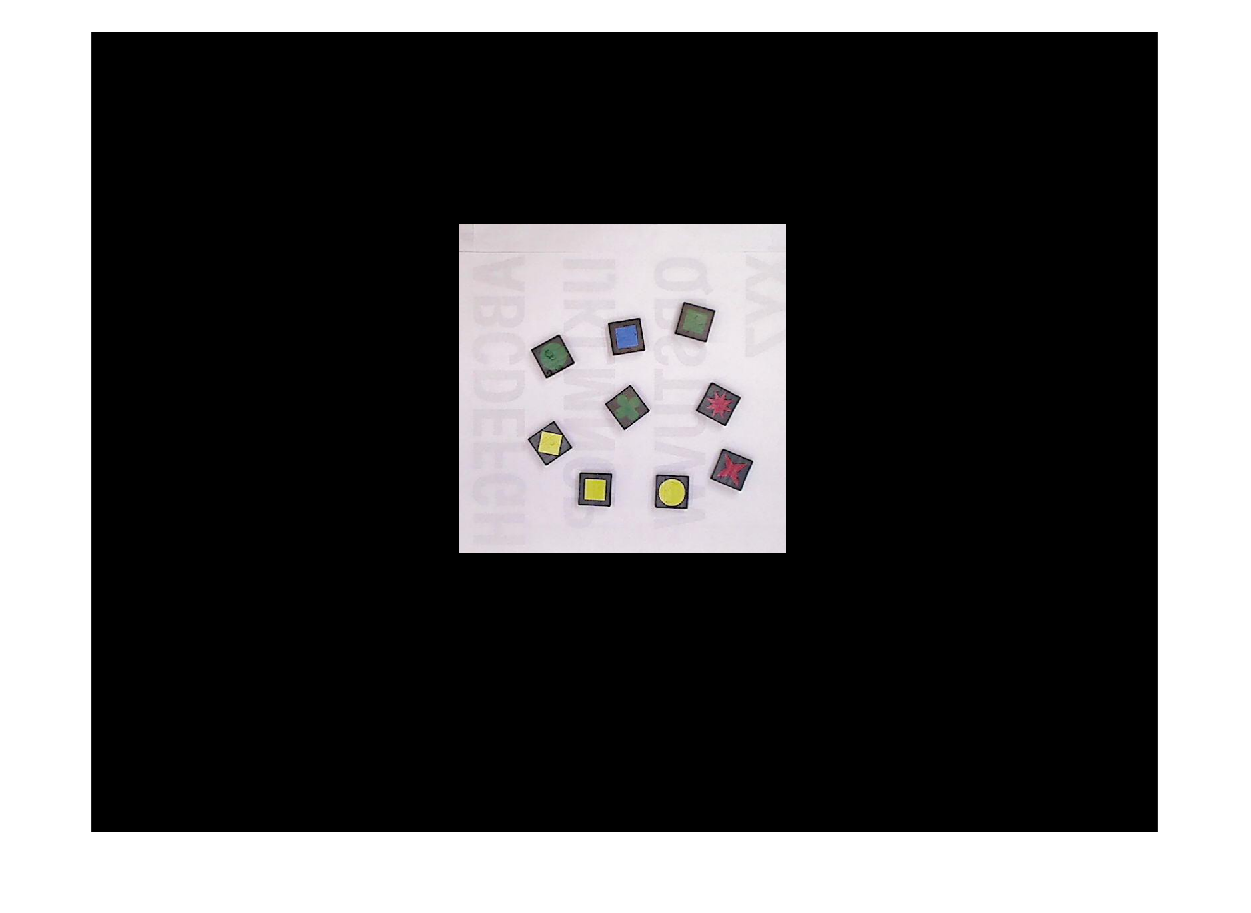

table_Img = imread('Proper_Pics\Patterns\Pattern1.jpg');
table_Img = undistortImage(table_Img, cameraParams);
table_Img = segmentSection(table_Img, 552, 1043, 288, 782);
figure; imshow(table_Img);

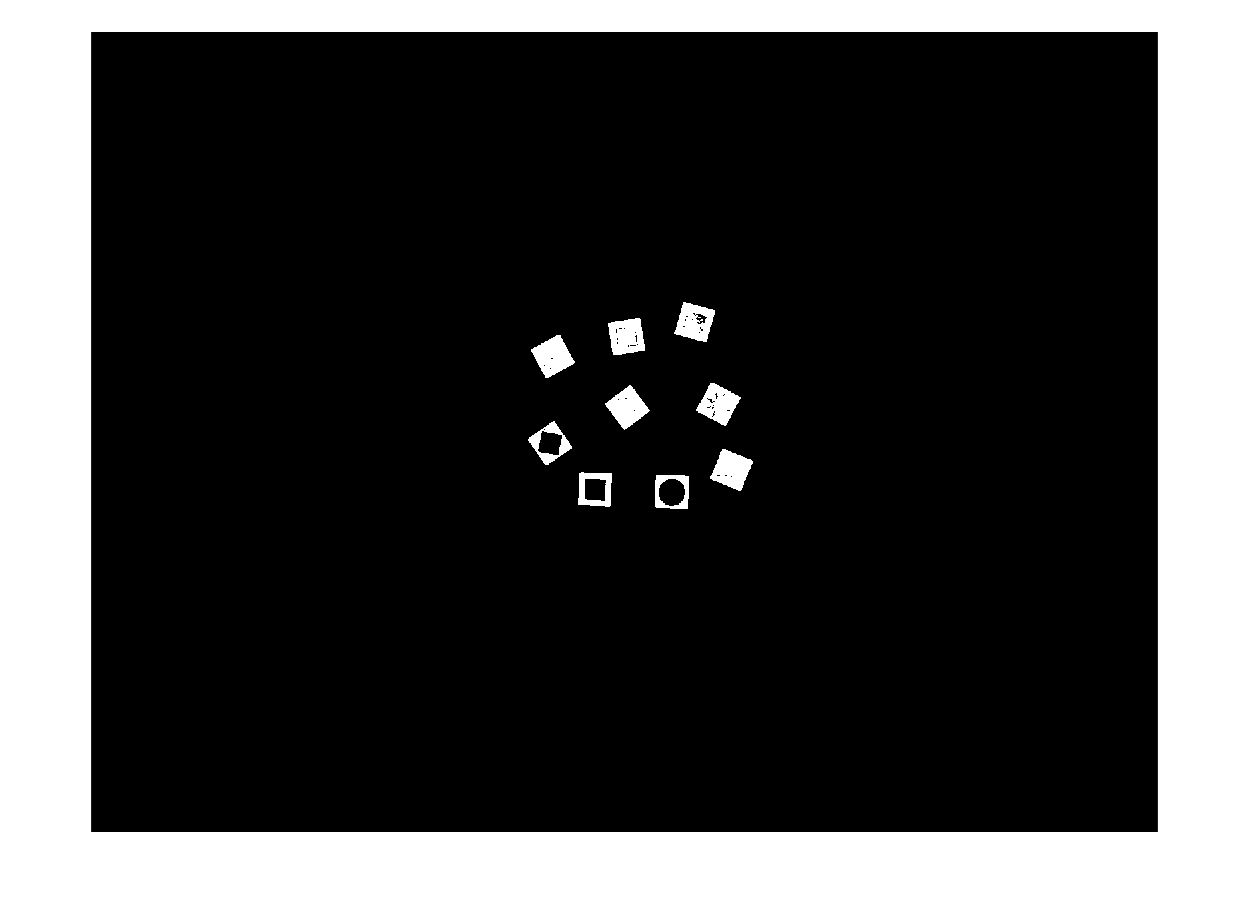


table_ImgBW = ~im2bw(table_Img);
table_ImgBW = segmentSection(table_ImgBW, 552, 1043, 288, 782);
table_ImgBW = removeLettersAndNumbers(table_ImgBW);
table_ImgBW = bwareaopen(table_ImgBW,100);
figure; imshow(table_ImgBW);

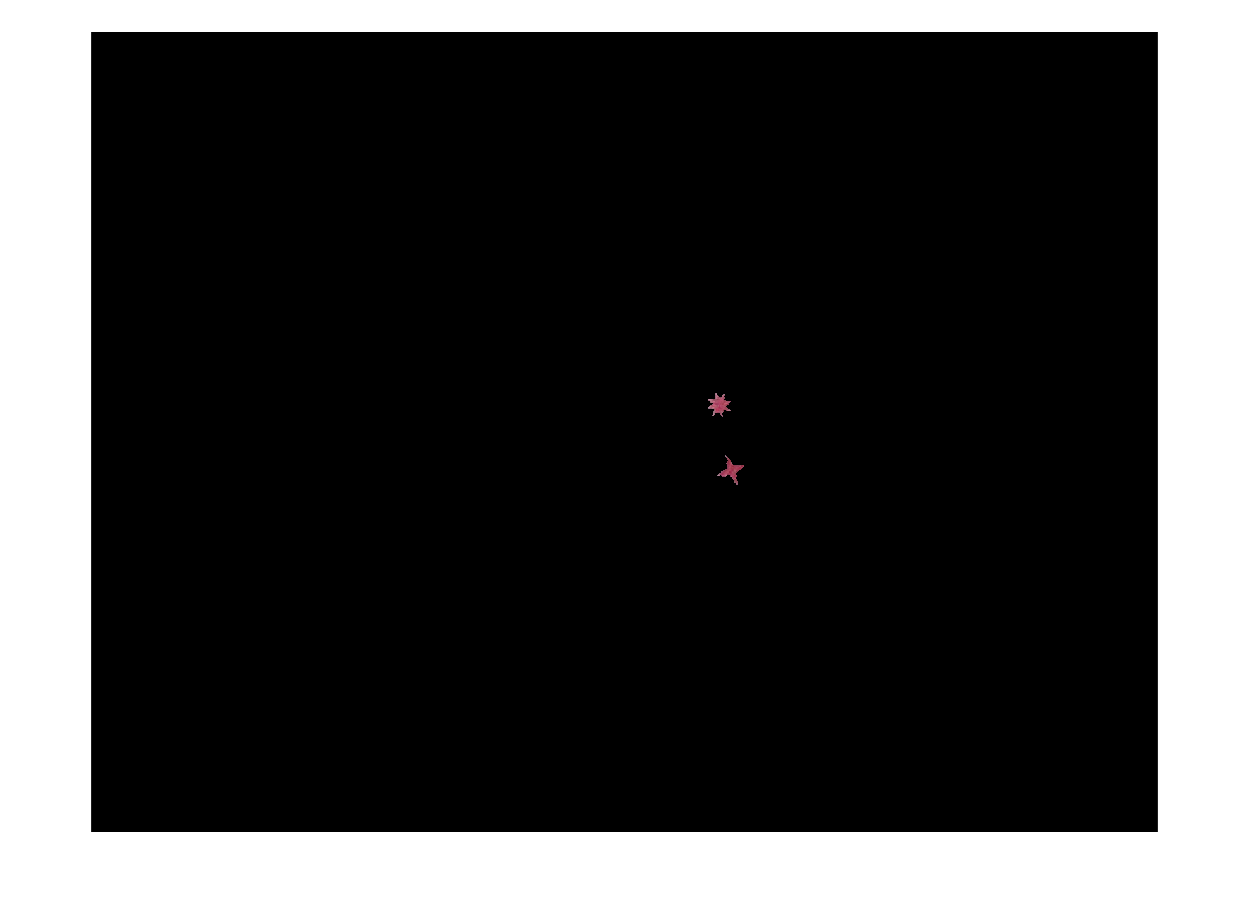


shapesAndProperties = [];

%% filter all colours
% red
[myPatternRedBW,myPatternRed] = createPatternRedMask(table_Img);
myPatternRedBW = imfill(myPatternRedBW,'holes');
myPatternRedBW = bwareaopen(myPatternRedBW,100);
%myPatternRedBW = bwmorph(myPatternRedBW, 'majority');
figure; imshow(myPatternRed);

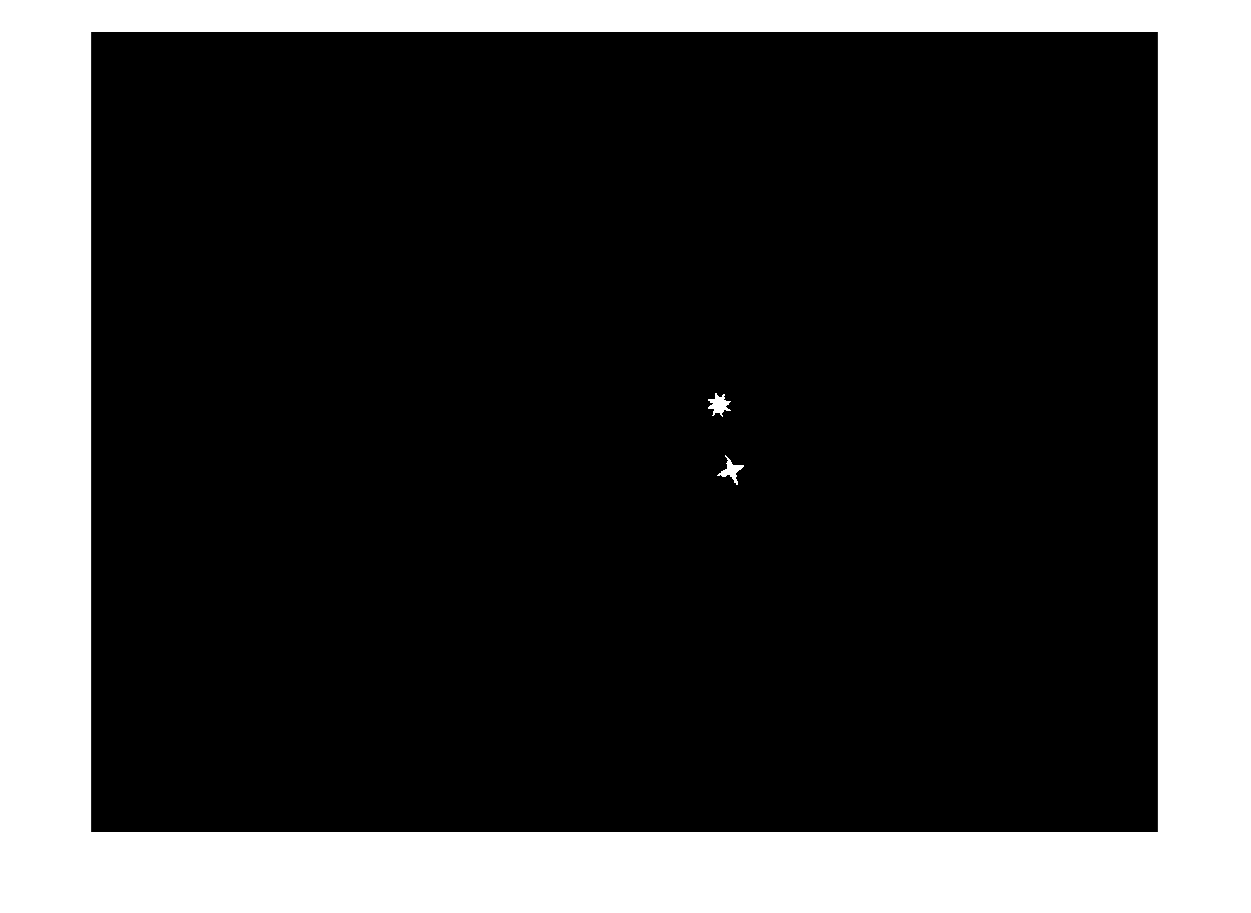

figure; imshow(myPatternRedBW);

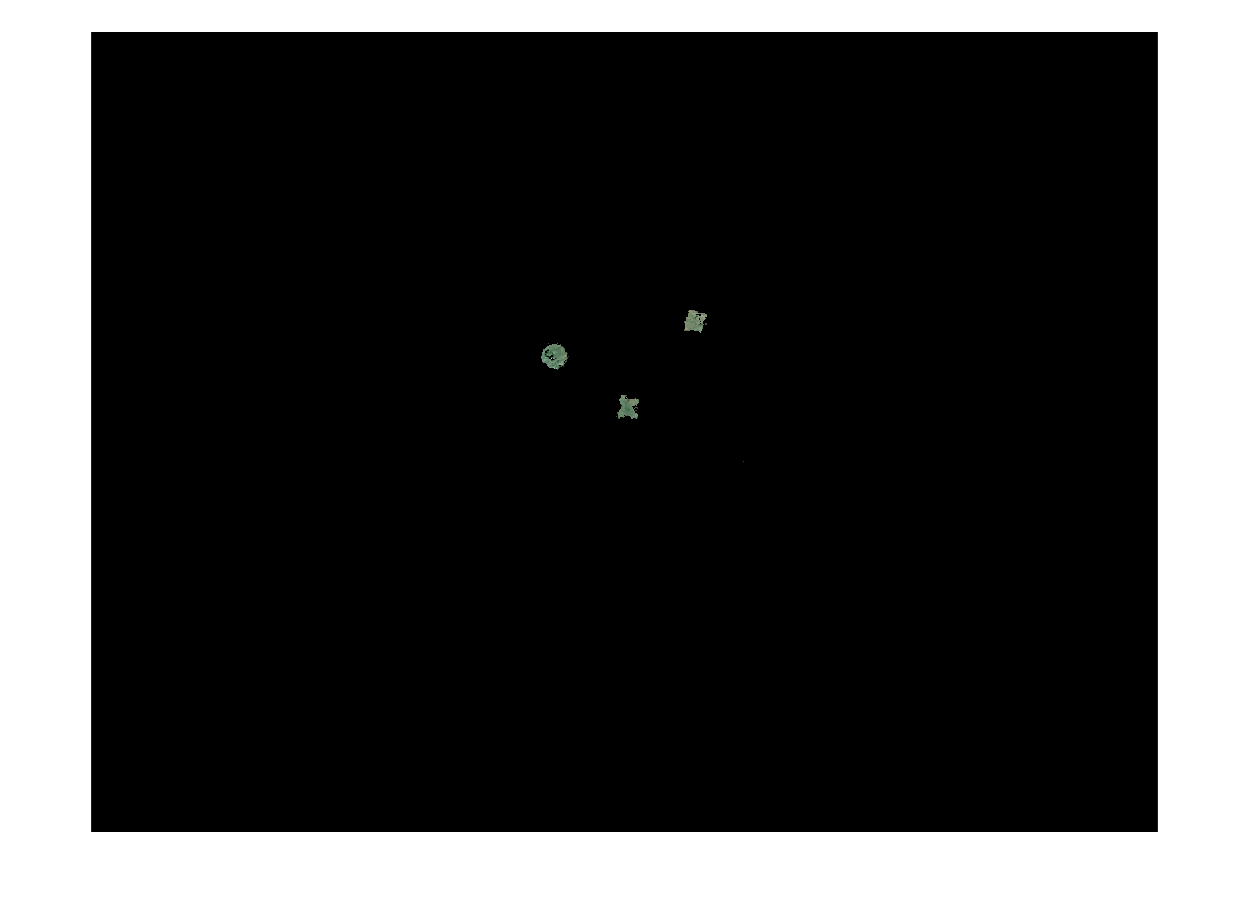


% green
% green's bit more sensitive 
table_Img = imsharpen(table_Img, 'Radius', 5, 'Amount', 1.5);
[myPatternGreenBW,myPatternGreen] = createPatternGreenMask(table_Img);
myPatternGreenBW = bwareaopen(myPatternGreenBW,100);
myPatternGreenBW = imfill(myPatternGreenBW,'holes');
figure; imshow(myPatternGreen);

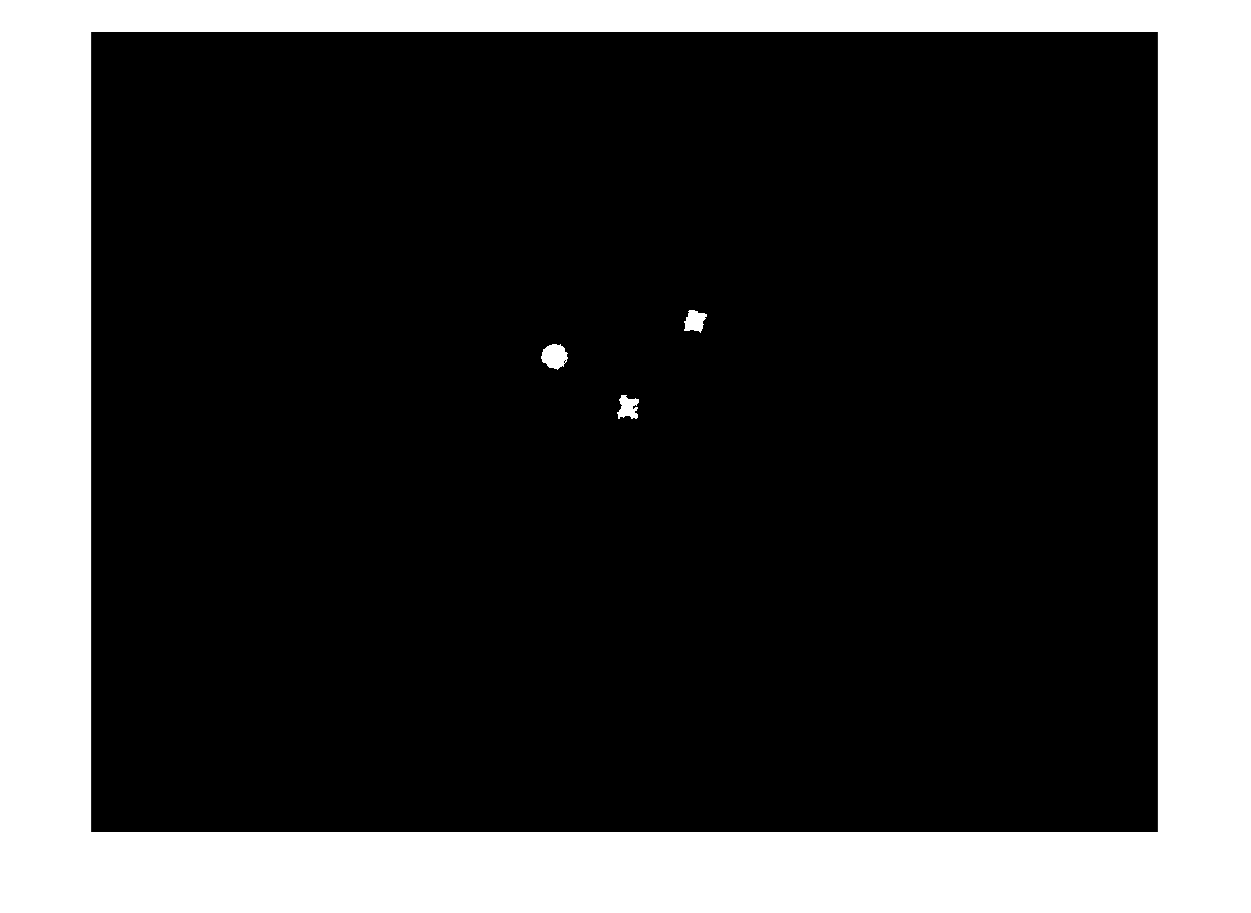

figure; imshow(myPatternGreenBW);

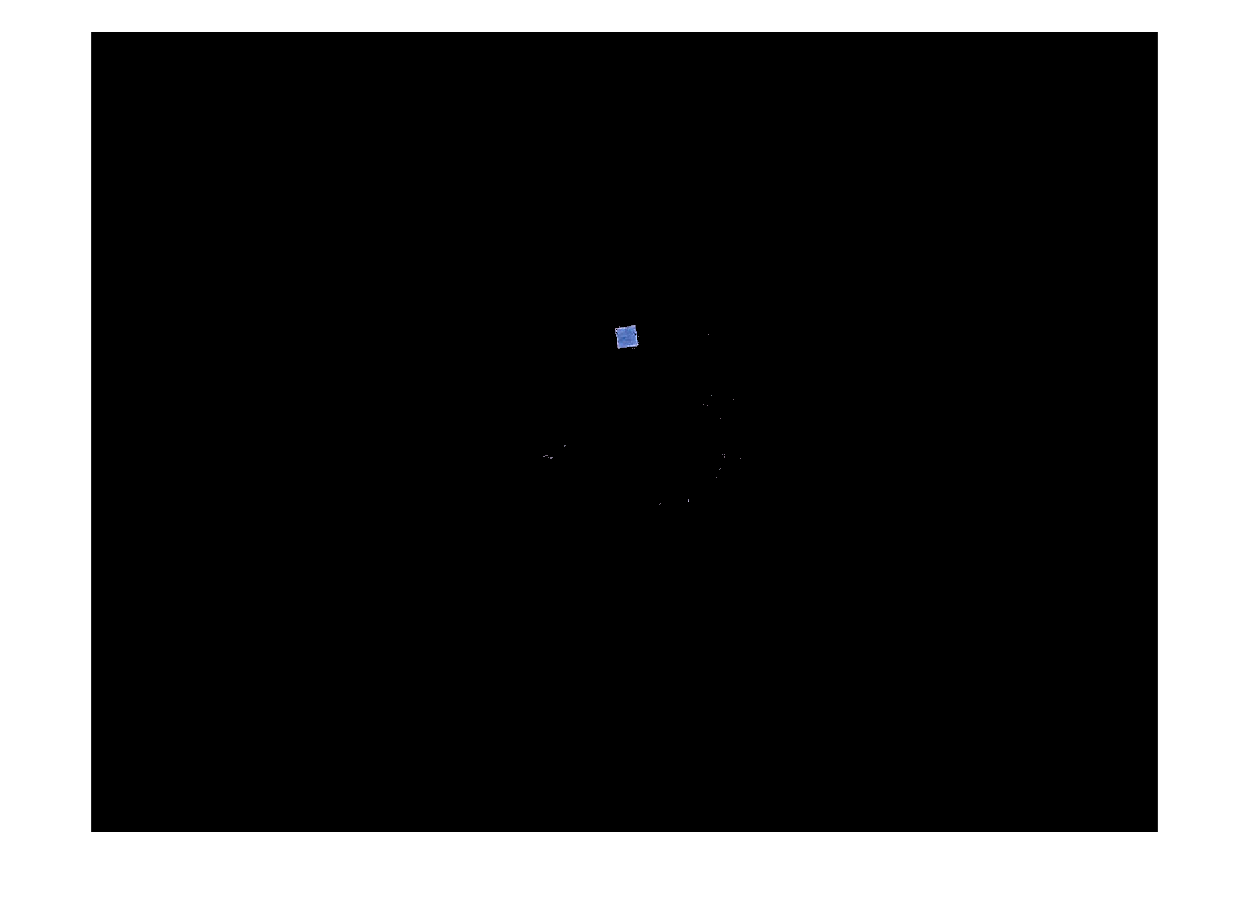


% Blue
[myPatternBlueBW,myPatternBlue] = createPatternBlueMask(table_Img);
myPatternBlueBW = bwareaopen(myPatternBlueBW,200);
figure; imshow(myPatternBlue);

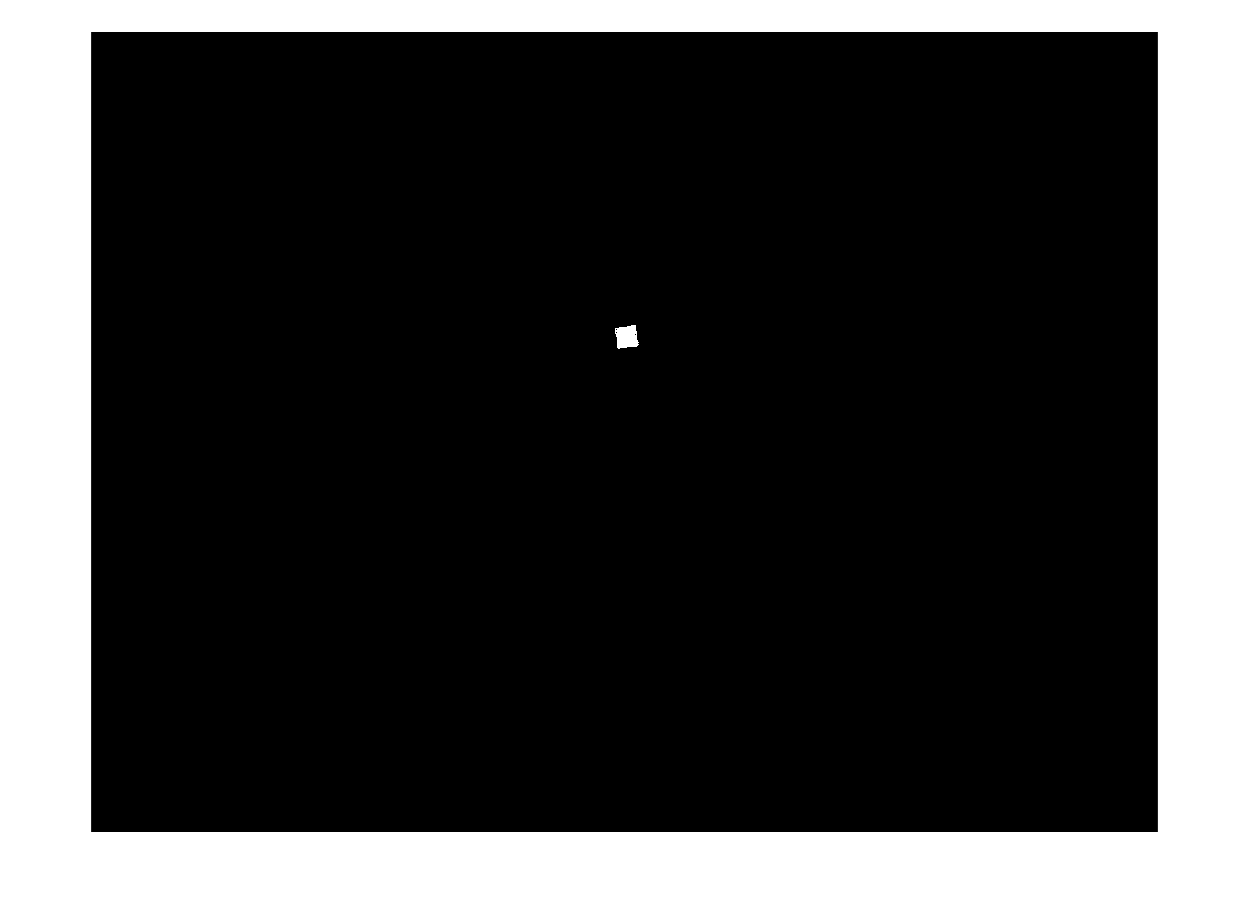

figure; imshow(myPatternBlueBW);

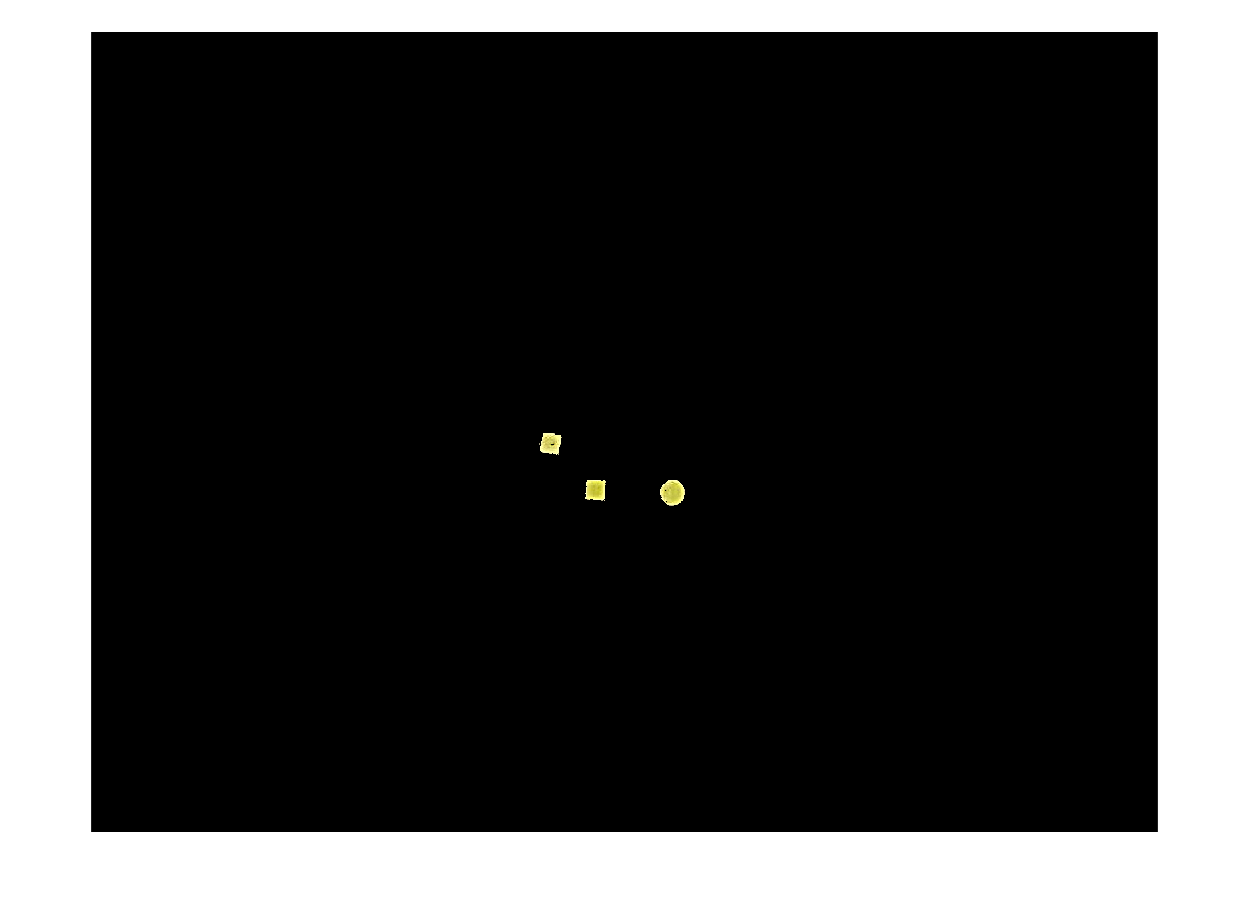


% Yellow
[myPatternYellowBW,myPatternYellow] = createPatternYellowMask(table_Img);
myPatternYellowBW = bwareaopen(myPatternYellowBW,200);
figure; imshow(myPatternYellow);

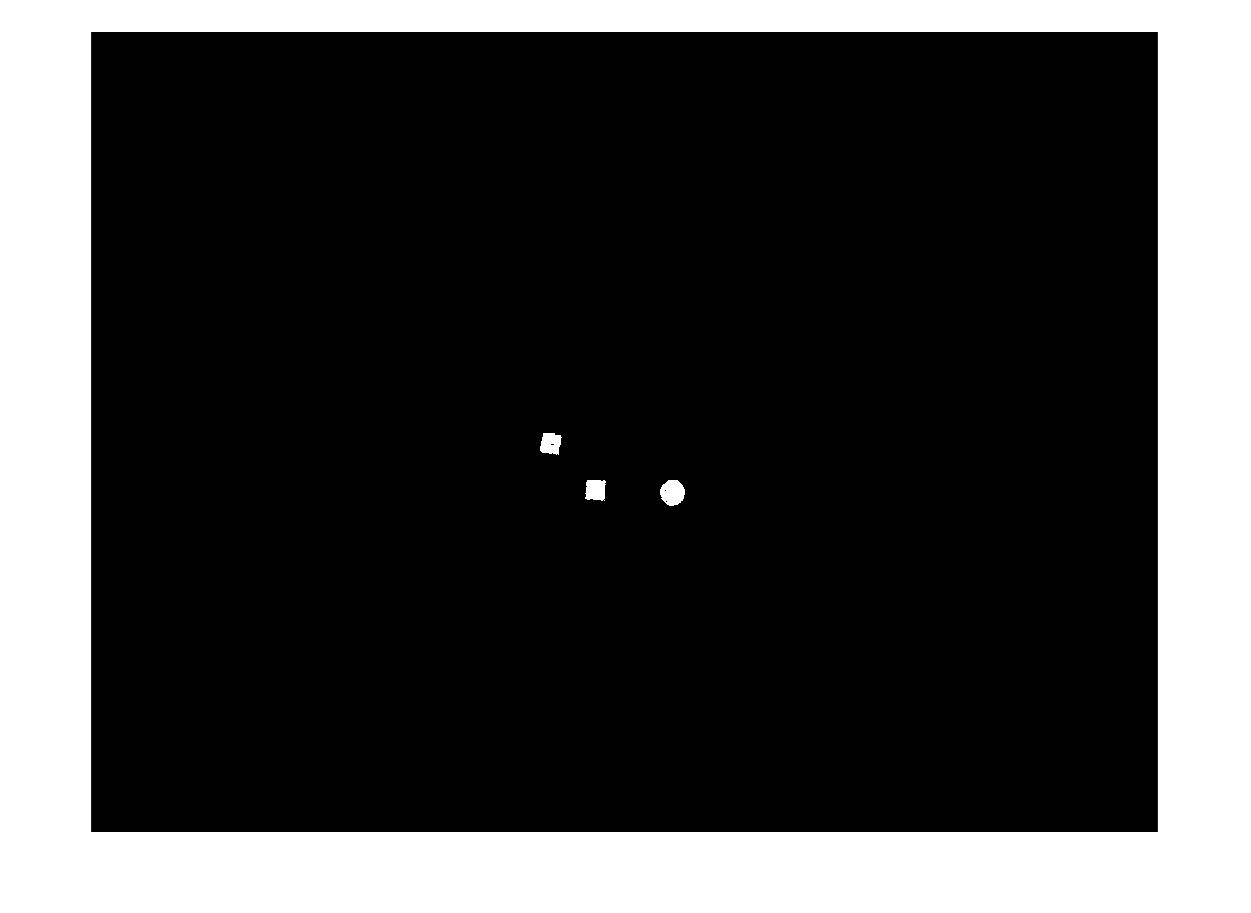

figure; imshow(myPatternYellowBW);

    "Angle Calculated based on the pic below :)"



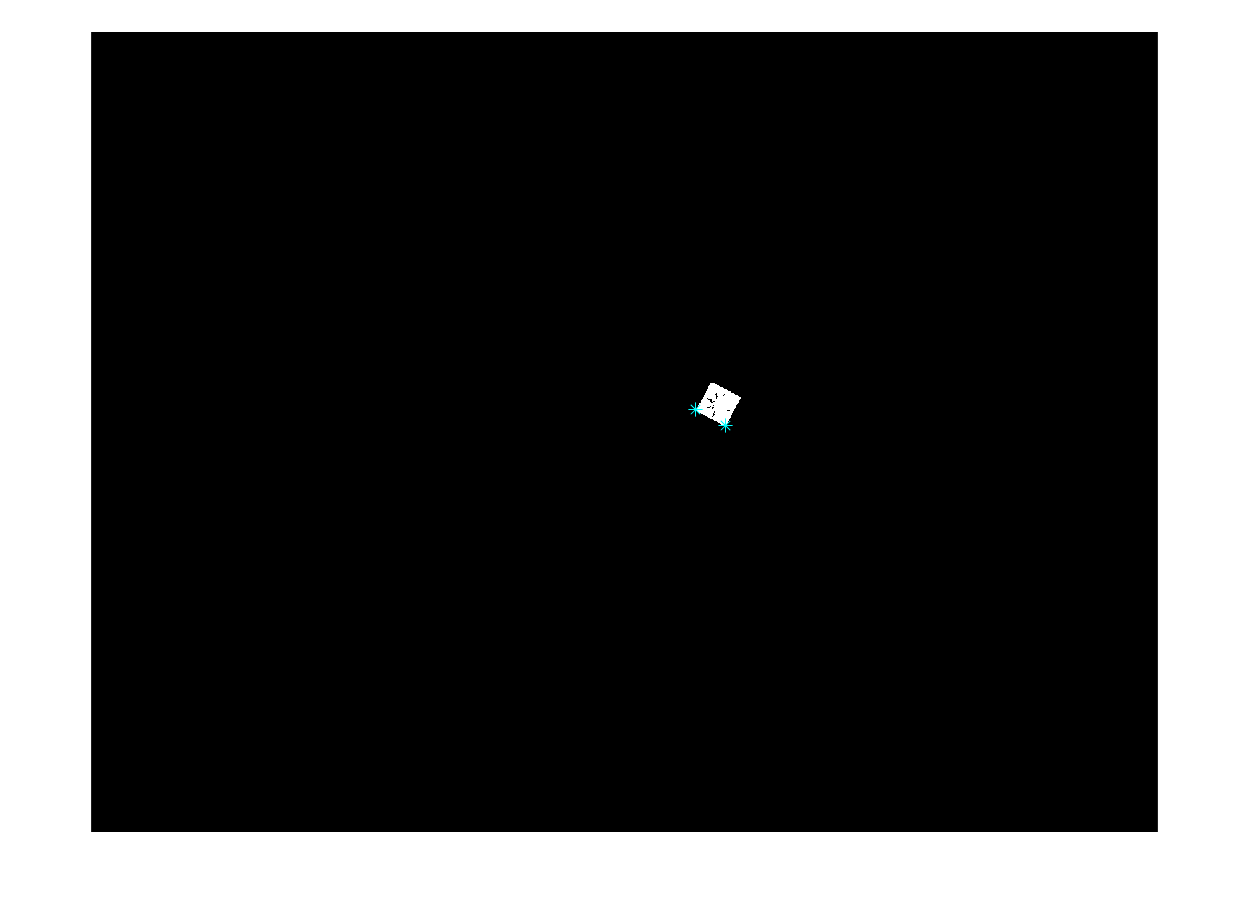

    "Angle Calculated based on the pic below :)"



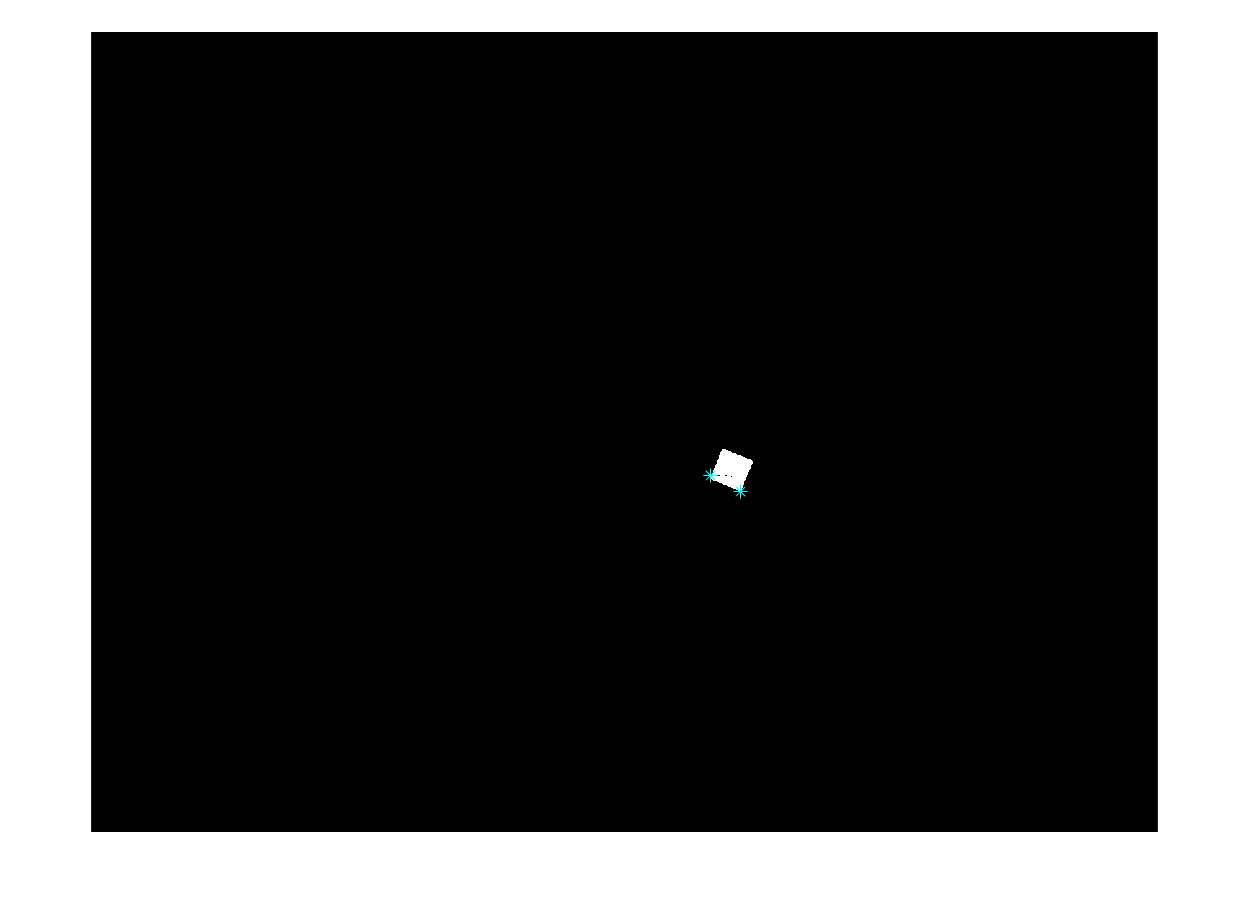


%% See if the colours exists in the pattern
redExists = find(myPatternRedBW);
greenExists = find(myPatternGreenBW);
blueExists = find(myPatternBlueBW);
yellowExists = find(myPatternYellowBW);

% process red
if length(redExists) > 50 
    cicleAreaThreshold = 1150;
    area2Threshold = 720;
    imopenSquareDim = 20;
    
    [redShape, redCentroid, redOrientation] = identifyAllShapes(myPatternRedBW, ...
        table_ImgBW, cicleAreaThreshold, area2Threshold);
else 
    display("No red exists in the pattern");
    redShape = [];
    redCentroid = [];
    redOrientation = [];
end 

    "Angle Calculated based on the pic below :)"



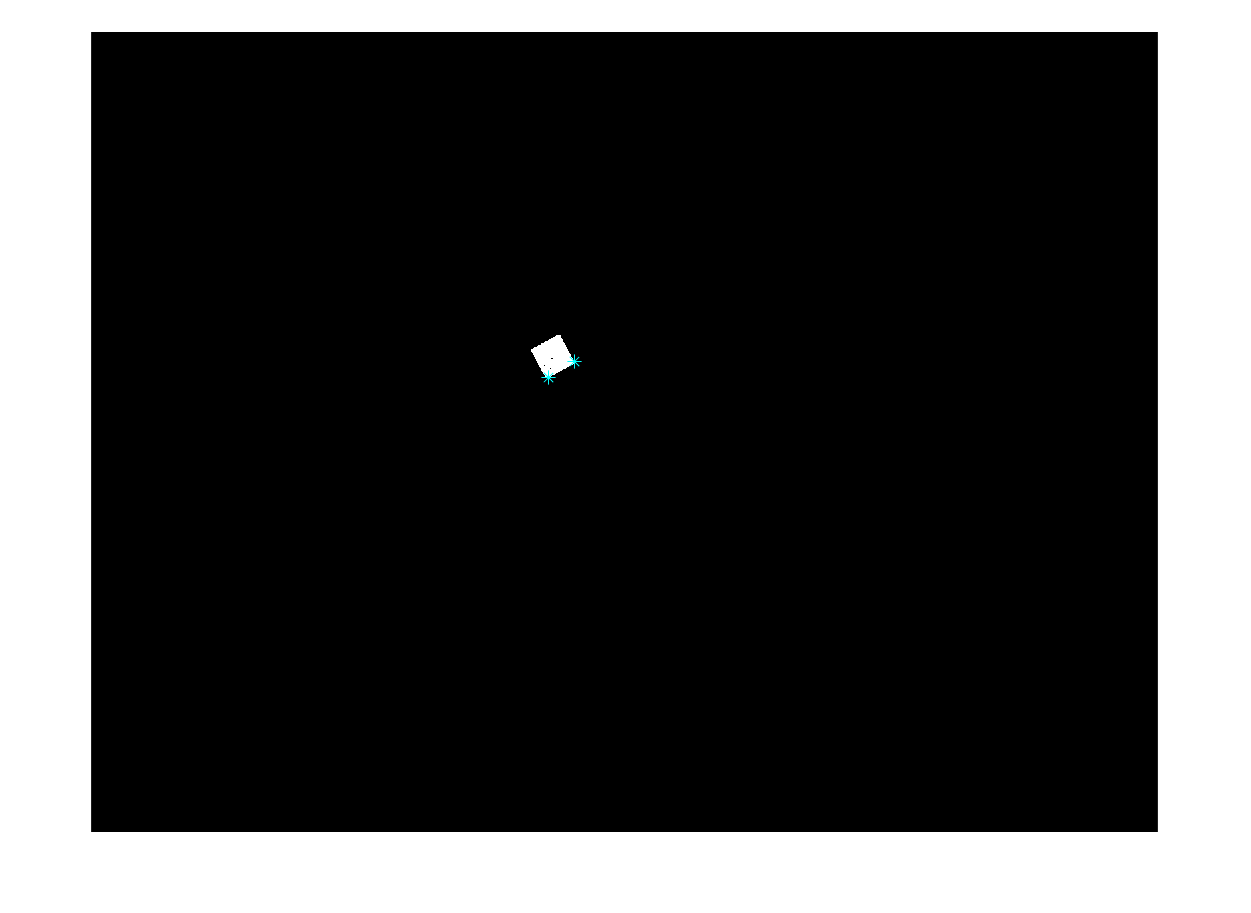

    "Angle Calculated based on the pic below :)"



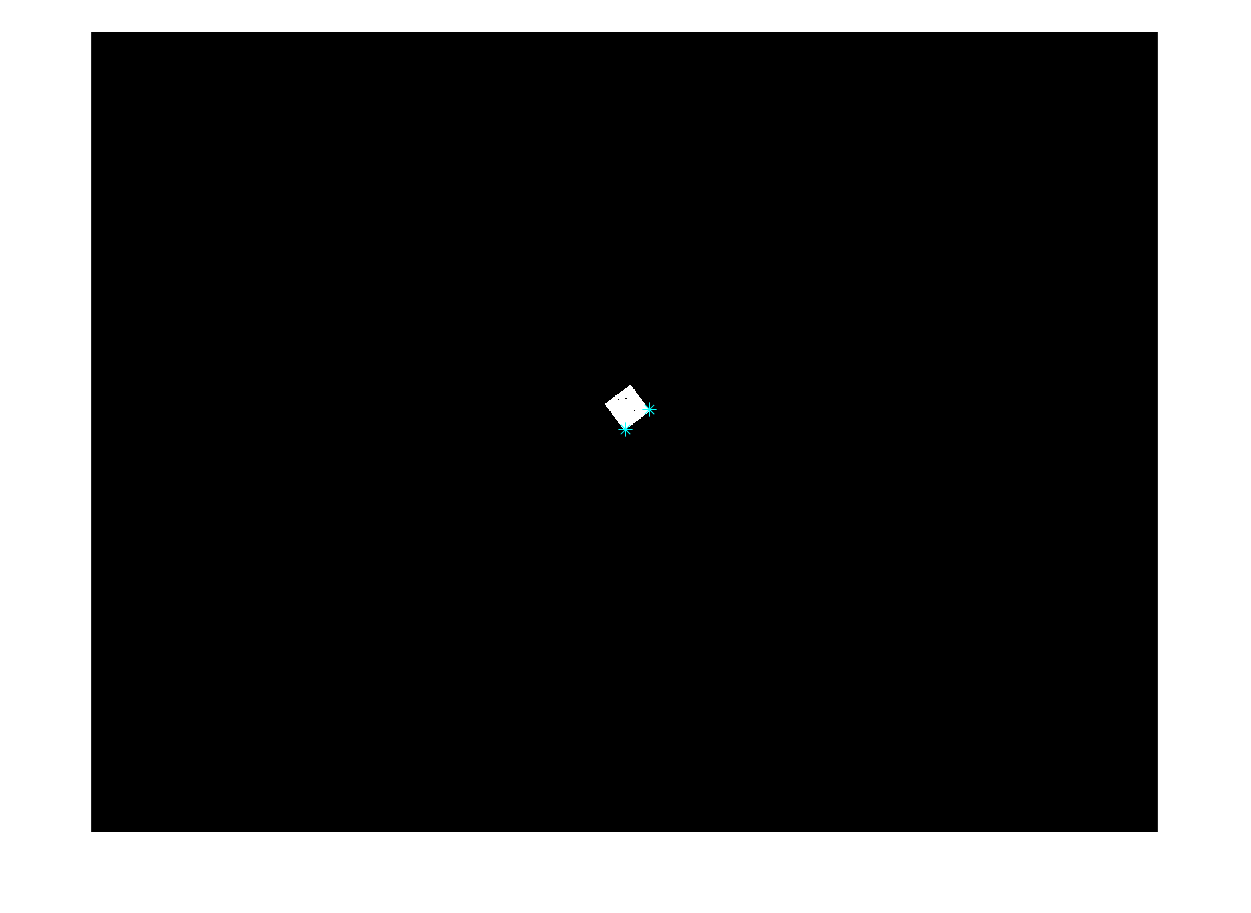

    "Angle Calculated based on the pic below :)"



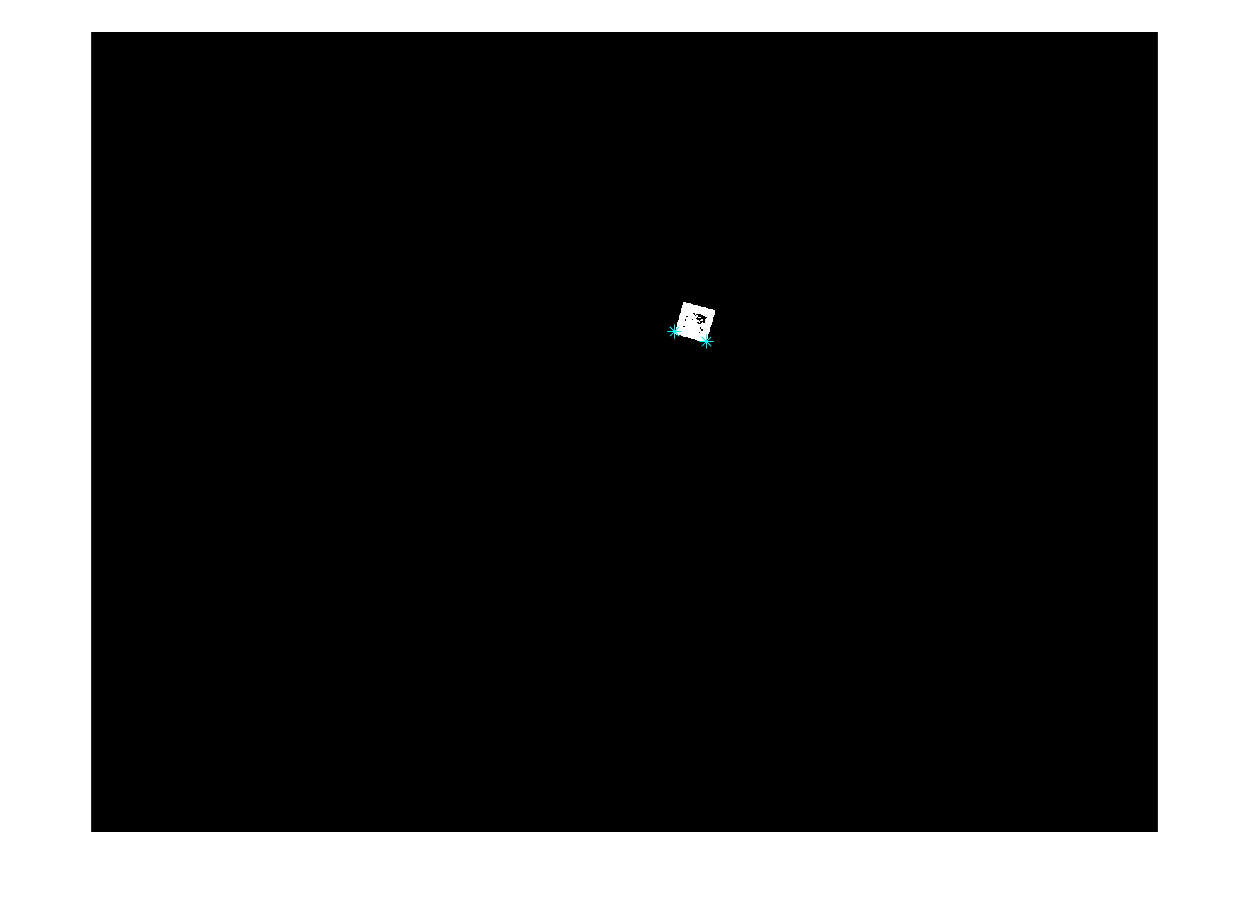


% process green
if length(greenExists) > 50 
    cicleAreaThreshold = 1115;
    area2Threshold = 820;
    [greenShape, greenCentroid, greenOrientation] = identifyAllShapes(myPatternGreenBW, ...
        table_ImgBW, cicleAreaThreshold, area2Threshold);
else
    display("No green exists in the pattern");
    greenShape = [];
    greenCentroid = [];
    greenOrientation = [];
end 

    "Angle Calculated based on the pic below :)"



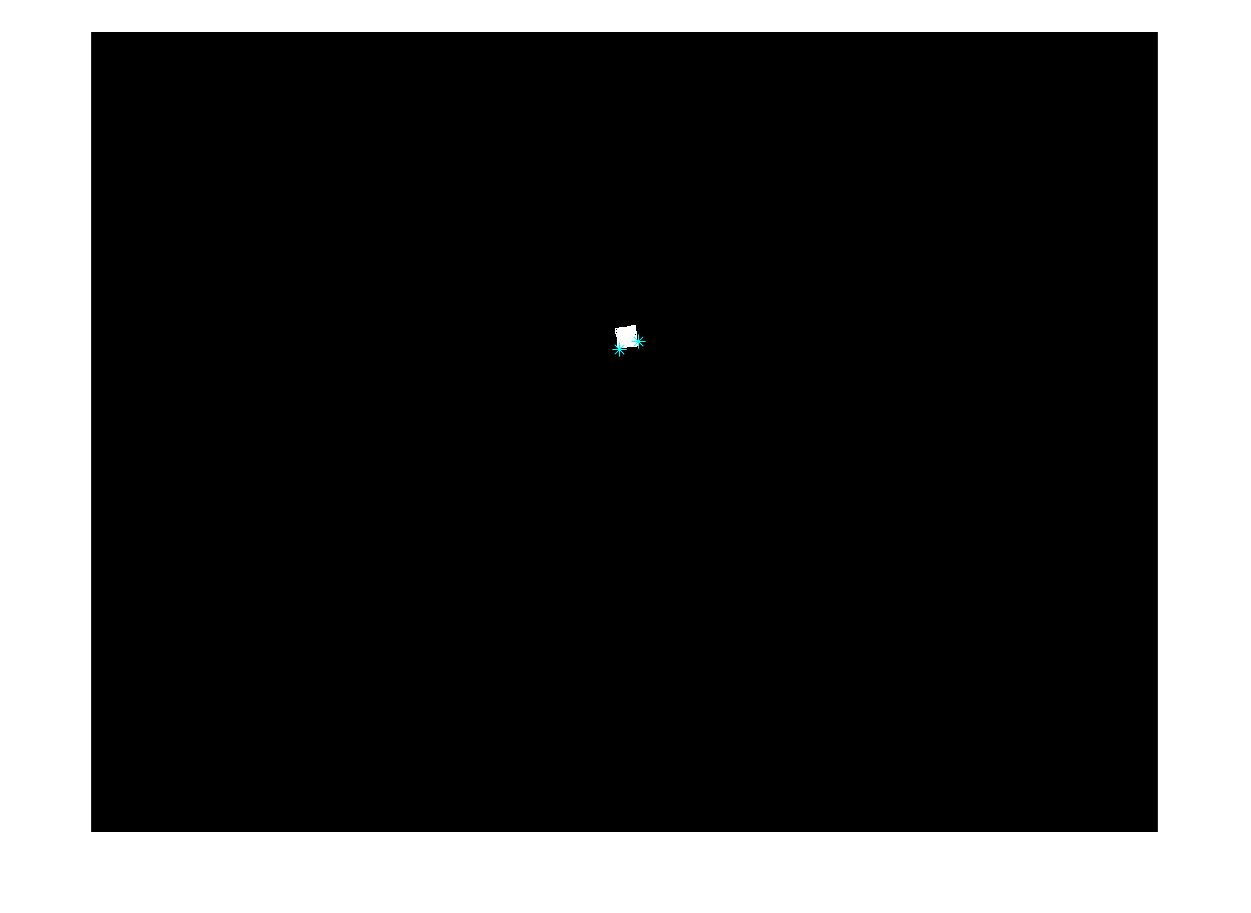

shpAngle =        21.448


    "Angle Calculated based on the pic below :)"



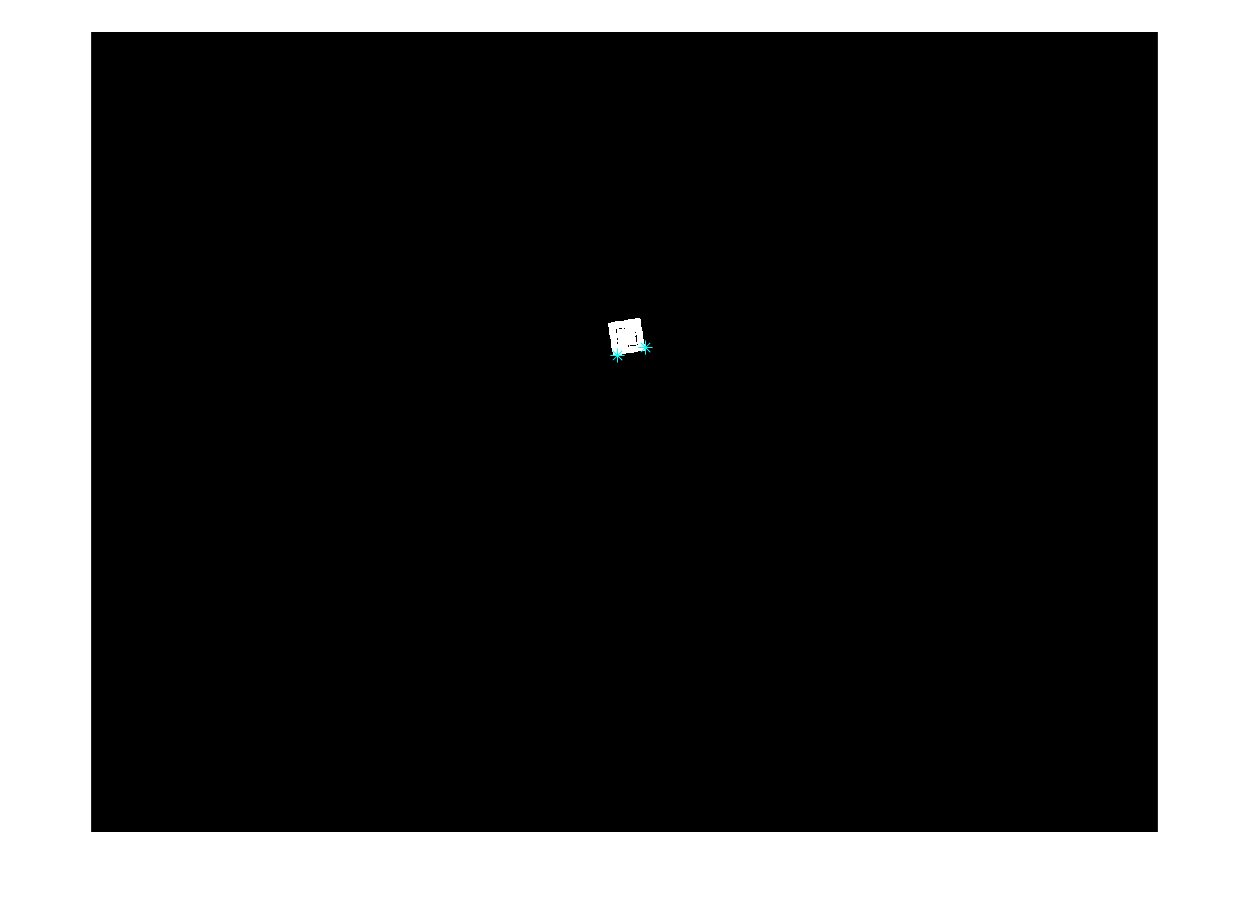

blockAngle =        15.018


    "Angle Calculated based on the pic below :)"




%process blue
if length(blueExists) > 50 
    cicleAreaThreshold = 1150;
    area2Threshold = 875;
    imopenSquareDim = 20;
    [blueShape, blueCentroid, blueOrientation] = identifyAllShapes(myPatternBlueBW, ...
        table_ImgBW, cicleAreaThreshold, area2Threshold);
else
    display("No blue exists in the pattern");
    blueShape = [];
    blueCentroid = [];
    blueOrientation = [];
end 

    "Angle Calculated based on the pic below :)"



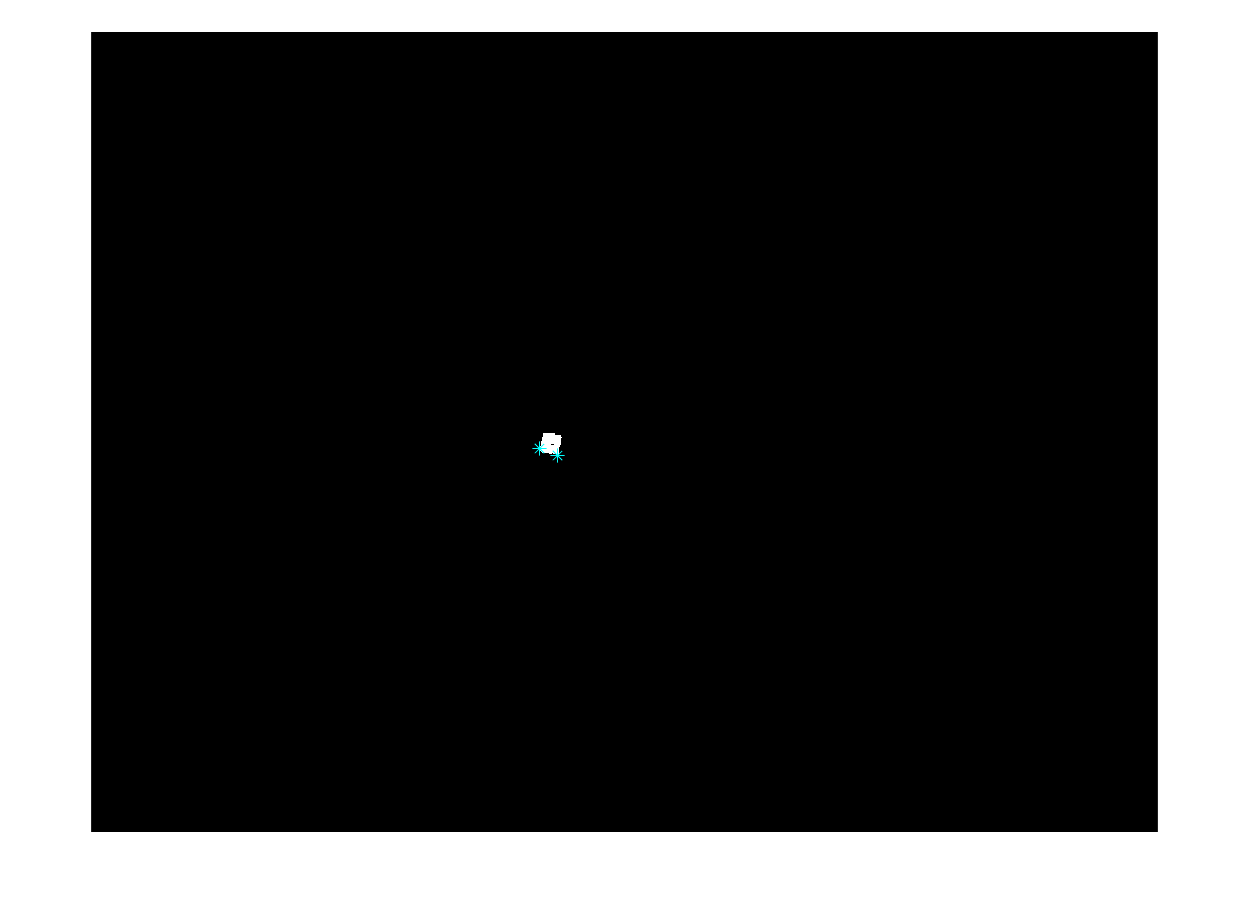

shpAngle =        70.346


    "Angle Calculated based on the pic below :)"



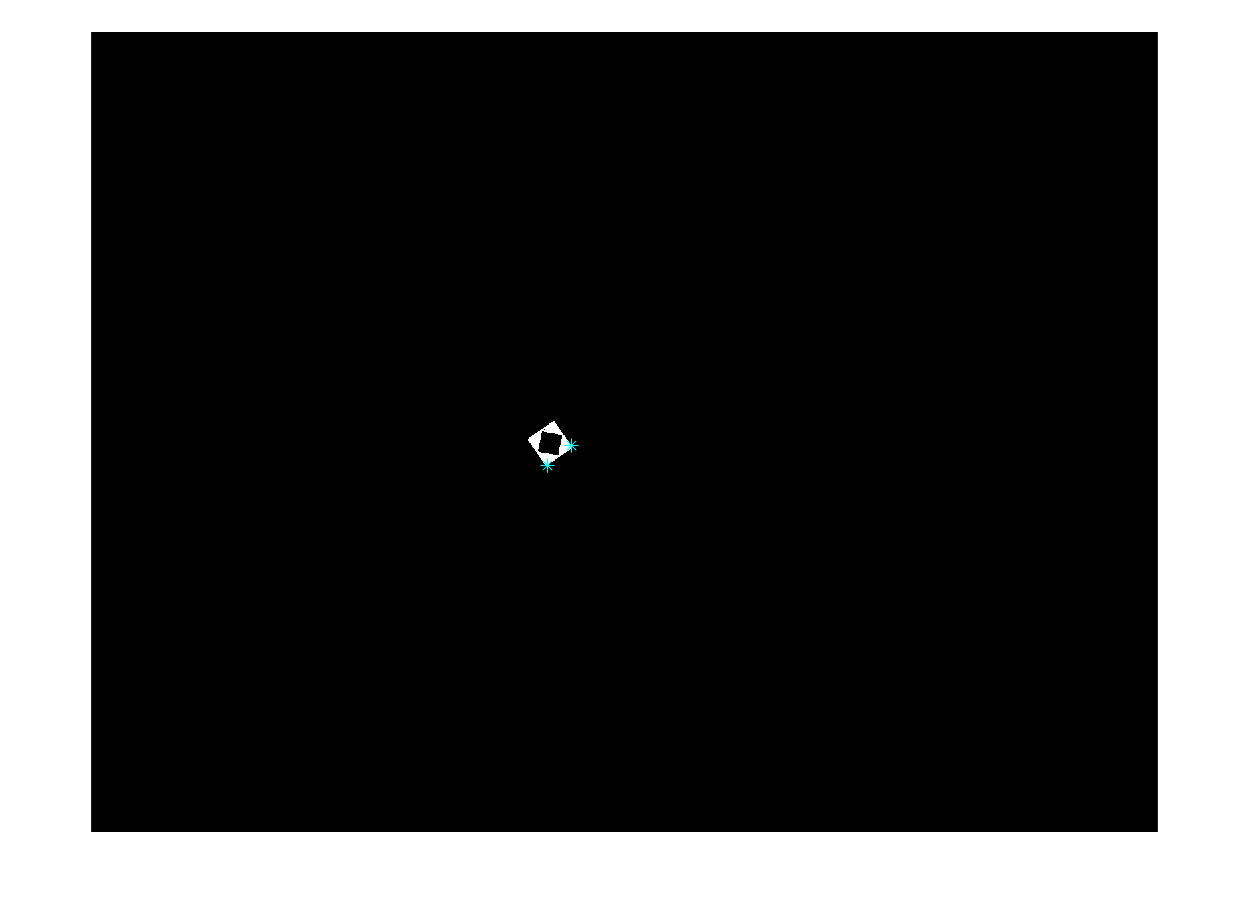

blockAngle =        38.089


    "Angle Calculated based on the pic below :)"



    "Angle Calculated based on the pic below :)"



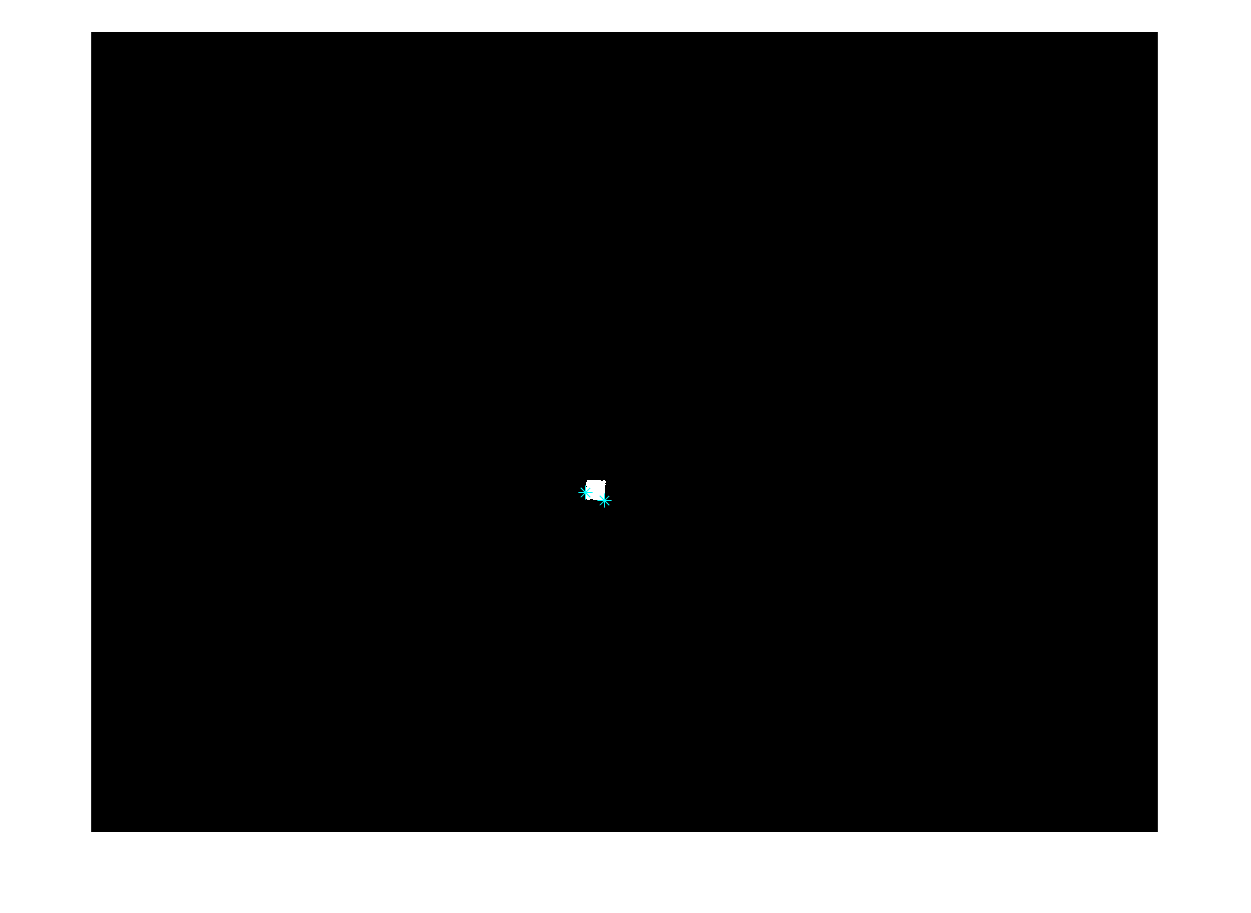

shpAngle =        67.521


    "Angle Calculated based on the pic below :)"



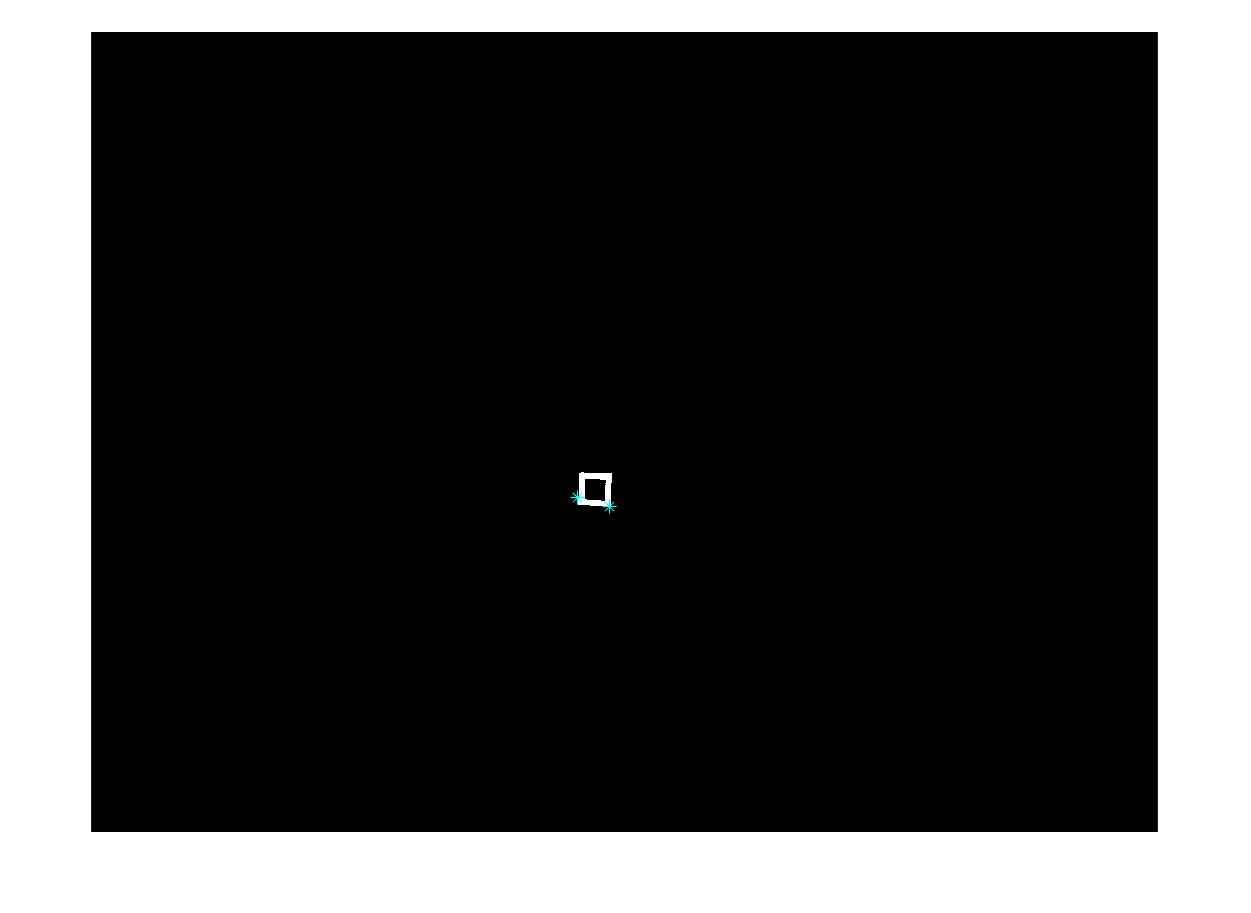

blockAngle =        74.846


    "Angle Calculated based on the pic below :)"



    "Angle Calculated based on the pic below :)"



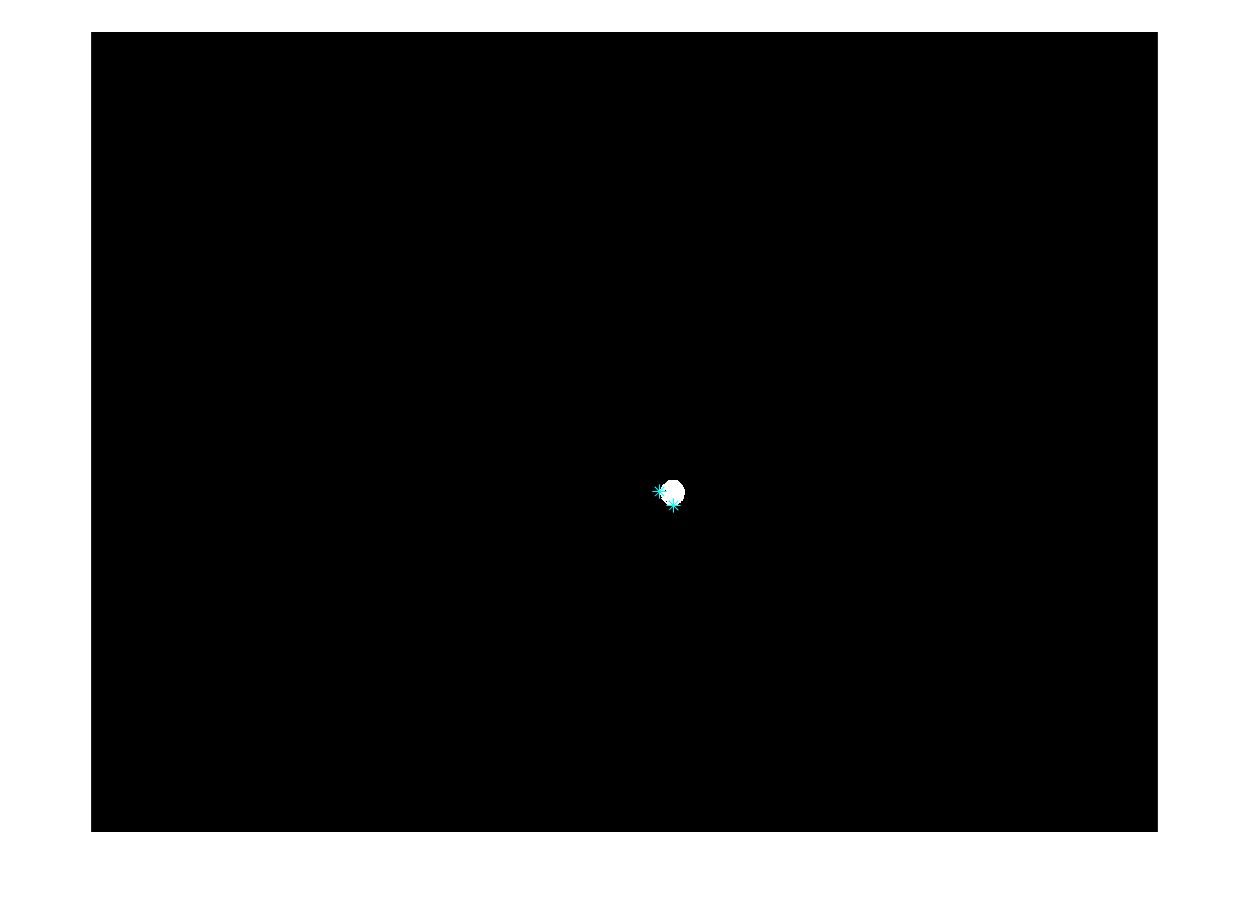

shpAngle =     45


    "Angle Calculated based on the pic below :)"



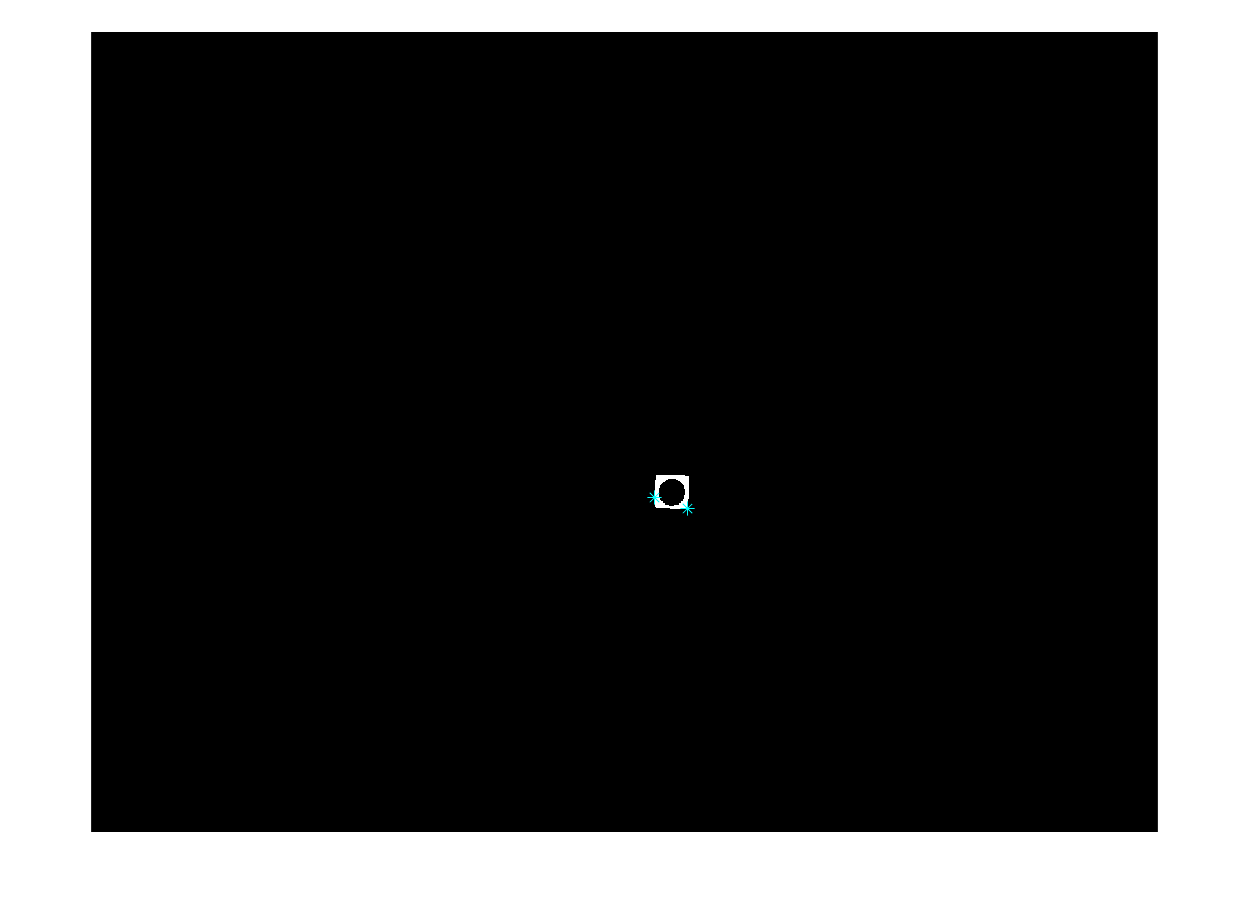

blockAngle =        71.222


    "Angle Calculated based on the pic below :)"




% process yellow
if length(yellowExists) > 50   
    cicleAreaThreshold = 1150;
    area2Threshold = 720;
    imopenSquareDim = 20;
    [yellowShape, yellowCentroid, yellowOrientation] = identifyAllShapes(myPatternYellowBW, ...
        table_ImgBW, cicleAreaThreshold, area2Threshold);
else
    display("No yellow exists in the pattern");
    yellowShape = [];
    yellowCentroid = [];
    yellowOrientation = [];
end


shapesAndProperties = [ones(size(redShape, 1), 1)*red redShape redCentroid redOrientation;...
    ones(size(greenShape, 1), 1)*green greenShape greenCentroid greenOrientation;...
    ones(size(blueShape, 1), 1)*blue blueShape blueCentroid blueOrientation;...
    ones(size(yellowShape, 1), 1)*yellow yellowShape yellowCentroid yellowOrientation]

shapesAndProperties =           1.1          2.6       942.46       559.56       60.945
          1.1          2.6       961.07        658.2       62.928
          1.2          2.1       695.29       487.02       32.661
          1.2          2.5       805.75       563.91       39.036
          1.2          2.5       905.99       434.14       72.646
          1.3          2.4        803.7       458.03       15.018
          1.4          2.3       689.61       617.81       38.089
          1.4          2.4       757.02       687.48       74.846
          1.4          2.3       872.76       691.63       71.222
